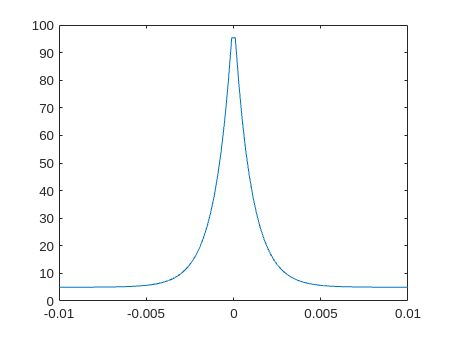

clear;
relvel = linspace(-0.01, 0.01, 100);
AllParams;
friction = @(rel) drivetraction_model(rel, 0, 0, wheels.staticdrivetraction, wheels.lineardrivetraction, wheels.subwheels);
plot(relvel, friction(relvel)./relvel)

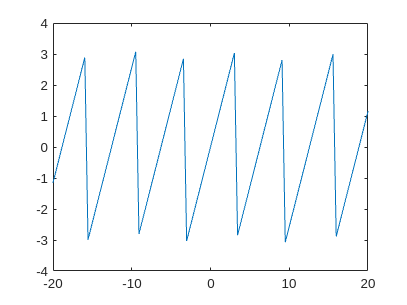

clear;
angle_error = linspace(-20, 20, 100);
plot(angle_error, limit_angle(angle_error))

AllParams;
turn = [angle_error;angle_error;angle_error;angle_error]

turn =   -20.0000  -19.5960  -19.1919  -18.7879  -18.3838  -17.9798  -17.5758  -17.1717  -16.7677  -16.3636  -15.9596  -15.5556  -15.1515  -14.7475  -14.3434  -13.9394  -13.5354  -13.1313  -12.7273  -12.3232  -11.9192  -11.5152  -11.1111  -10.7071  -10.3030   -9.8990   -9.4949   -9.0909   -8.6869   -8.2828   -7.8788   -7.4747   -7.0707   -6.6667   -6.2626   -5.8586   -5.4545   -5.0505   -4.6465   -4.2424   -3.8384   -3.4343   -3.0303   -2.6263   -2.2222   -1.8182   -1.4141   -1.0101   -0.6061   -0.2020
  -20.0000  -19.5960  -19.1919  -18.7879  -18.3838  -17.9798  -17.5758  -17.1717  -16.7677  -16.3636  -15.9596  -15.5556  -15.1515  -14.7475  -14.3434  -13.9394  -13.5354  -13.1313  -12.7273  -12.3232  -11.9192  -11.5152  -11.1111  -10.7071  -10.3030   -9.8990   -9.4949   -9.0909   -8.6869   -8.2828   -7.8788   -7.4747   -7.0707   -6.6667   -6.2626   -5.8586   -5.4545   -5.0505   -4.6465   -4.2424   -3.8384   -3.4343   -3.0303   -2.6263   -2.2222   -1.8182   -1.4141   -1.0101   -0.6061  

turn_out = turn_prio_desaturator(turn, [0;0;0;0], ctrl.fmax)

turn_utilization = 1×100 single row vector
    3.6585    3.5846    3.5107    3.4368    3.3629    3.2890    3.2151    3.1412    3.0673    2.9933    2.9194    2.8455    2.7716    2.6977    2.6238    2.5499    2.4760    2.4021    2.3282    2.2542    2.1803    2.1064    2.0325    1.9586    1.8847    1.8108    1.7369    1.6630    1.5891    1.5152    1.4412    1.3673    1.2934    1.2195    1.1456    1.0717    0.9978    0.9239    0.8500    0.7761    0.7021    0.6282    0.5543    0.4804    0.4065    0.3326    0.2587    0.1848    0.1109    0.0370


turn_out = 4×100 single matrix
   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4545   -5.0505   -4.6465   -4.2424   -3.8384   -3.4343   -3.0303   -2.6263   -2.2222   -1.8182   -1.4141   -1.0101   -0.6061   -0.2020
   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4667   -5.4545   -5.0505   -4.6465   -4.2424   -3.8384   -3.4343   -3.0303   -2.6263   -2.2222   -1.8182   -1.41

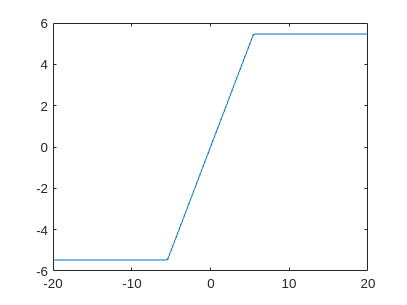

plot(angle_error, turn_out(1,:))